clc;
clear;
x=imread('20250119_134256.JPG');

% --------filter coeff.-----------%
f1=[1 1 1;1 1 1;1 1 1];
f2=[1 0 -1;1 0 -1;1 0 -1];
f3=[1 1 1;0 0 0;-1 -1 -1];

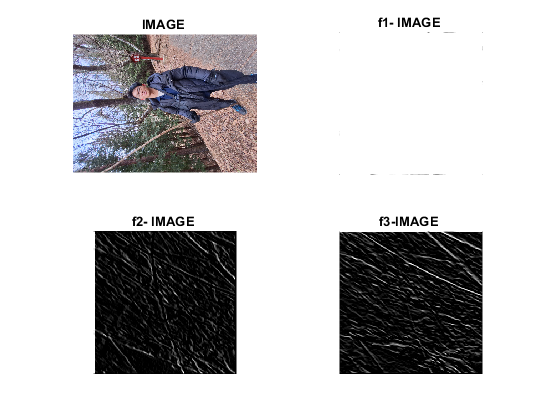

% -------filtering-----------%
x1=x(1:256,1:256);
y1=conv2(x1,f1);
y2=conv2(x1,f2);
y3=conv2(x1,f3);
subplot(2,2,1);imshow(x);title('IMAGE ')
subplot(2,2,2);imshow(uint8((y1)));title('f1- IMAGE ')
subplot(2,2,3);imshow(uint8((y2)));title('f2- IMAGE ')
subplot(2,2,4);imshow(uint8((y3)));title('f3-IMAGE ')